# **Image-Based Defect Detection Report**

%% ------------------- PATH SETUP -----------------------------
% If you are reading this, I failed at hiding this. Hello!
try
    repoDir = fileparts(matlab.desktop.editor.getActiveFilename());
catch
    repoDir = fileparts(mfilename("fullpath"));
end

functionsDir        = fullfile(repoDir, "functions");
imageSampleSetsDir  = fullfile(repoDir, "imageSampleSets");
sampleDataFolder    = fullfile(imageSampleSetsDir, "sample_test_02", "images");   % 10 clean + 10 defect
resultsFile = fullfile(imageSampleSetsDir, "02DatasetResults_noFineScratch428Clean.mat"); % Results of the pre-override batch test (not final)

addpath(genpath(functionsDir));

netFileName    = "1785125303951_trainedInspectAI.mat";
netMatFile     = fullfile(repoDir, netFileName);
netReleaseURL  = "https://github.com/AndyV0/Defect-Detection-Pipeline---Wood-Grain/releases/download/1.0/1785125303951_trainedInspectAI.mat";

R = load(resultsFile, "fullResults");
fr = R.fullResults;

if exist(fullfile(functionsDir, "inspectPart.m"), "file") ~= 2
    error("batchTestRunner:missingFunction", ...
        "inspectPart.m not found in %s.\nMake sure inspectPart.m is in functions/, and scratchDetection.m / brushDetection.m are in functions/classicalDetection/ (or wherever they live under functions/ -- genpath adds all nested subfolders automatically).", functionsDir);
end
%%

## Introduction

This live script contains all information and visuals we have made for BTAD's 2nd dataset. This includes the methodology, results of batch testing, analysis of defect detection system, and the many, many problems we encountered along the way. The second dataset consists of images of wood grain-texture. These images are the focal point of this project. Here is an example of a clean image of wood for this dataset:

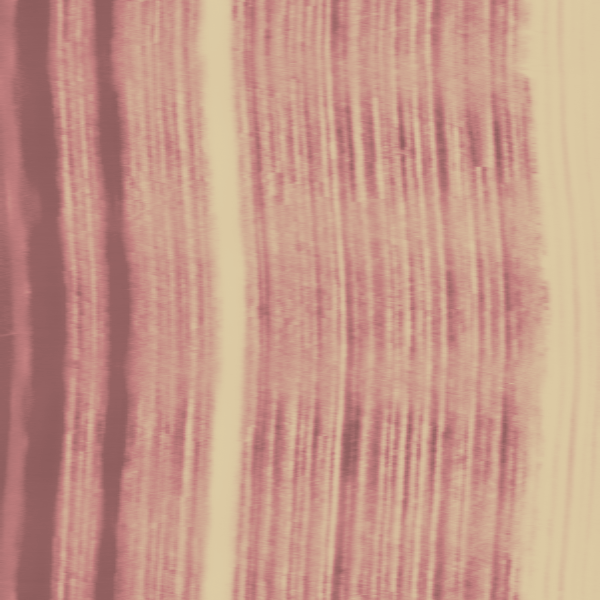

## 1. Approach & Methodology

We lived by the quote "a journey of a thousand miles begins with a single step." Our approach was thorough and calculated. Each section follows the approach that was taken in that specific task. We also believe in **repository automation** and **reproducible research**. All scripts should be easy to use, requiring a simple 'Run' at most. Functions should also be as easy to understand, with notes, usage, and explanations provided within each function's file. Furthermore, code has been used to create certain graphs. These pieces of code directly take from `.mat` files created from the functions and provide credibility to the metrics discussed in this report. 

### 1.1 Defining the Defects

The first step to any image defect detection system is defining the defects. Defect images in this dataset deviate from the natural, vertical graininess of the wood. These defective wood grain images are all categorized in one defect folder (test/ko). However, for clarity and documentation, our team has split the defects further into three distinct categories. The three categories are important in understanding our batch testing results:

#### Scratch Defect

A **scratch defect** is a physical surface flaw in the wood grain. They present as a **thin, elongated cut/scrape** into the wood surface. Scratches are **darker than the wood** surrounding them and they **run against the vertical grain, being inherently horizontal**. Scratches in the image are also a localized anomaly, meaning multiple scratch marks tend to be clumped up in one part of the image, never covering the whole image. In terms of classical image processing, the texture, shape, and direction of this defect make it easy to isolate. They are the most common defect in this dataset, and one that most defect images carry:

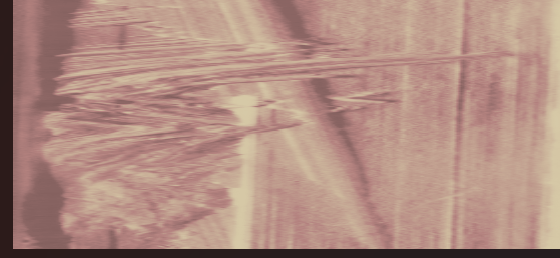

#### Brush Defect

A **brush defect** is a compact,** blob-shaped region **where the wood grain texture appears to be disrupted or covered over. These blobs present locally, replacing fine vertical grain pattern with a smoother, cross-grain patch. A brush defect is comprised of two regions: a boundary and an interior. The **boundary of a brush defect conflicts with vertical grain, **while the interior is too smooth for directional filters to measure. In terms of classical image processing, this makes the brush defect are harder to isolate, as their boundary and interiors share different properties. The interior being lighter color than the boundary makes a single defect isolation tool useless in capturing both, necessitating the use of multiple methods being employed simultaneously (FFT & Entropy Filter). 

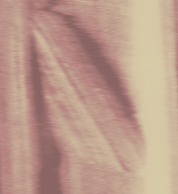

#### Super-Fine Scratch Defect

A super-fine scratch is the smallest defects in the dataset, yet make up 54% of defect images in the dataset. It presents as a **thin, elongated cut/scrape** into the wood surface, with a small caveat. **Super-fine scratches tend to only be a couple of pixels tall. **In terms of classical image processing, this scratch is deceptively difficult to isolate. Directional filters can detect these scratches, but the size of these defects makes them **EXTREMELY fragile to thresholding**. On the AI end, the small size of the defects combined with Resnet18's 224 × 224 pixels input make **the AI mostly ignores this defect. ** More information on the AI's failure in detecting these defects can be found in "Remaining Challenges."

### 1.2 Classical Detection Systems 

The clear categorization of defects allowed us to effectively set the foundation for a couple of detection systems. Each classical detection system used in this script has been worked on and reworked countless times for the express purpose of competing with the AI classifier. In trying to outperform the AI classifier, the classical detection can be used as a fallback option when the AI fails, which was the case in batch testing (explored in Design Decisions & Tradeoffs). 

Inital testing included eyeballing the masks against the defect images and concept testing different image processing techniques. This methodology was used for the first couple drafts of scratch and brush detection as our team was new to the image processing tools. However, a more efficient and effective process soon took over.

The aimless nature of trying to match the mask to the defect in the image was frustrating to work with, which is where the detailed detect categorization, small-scale batch testing, and evidence metrics data collecting was employed. Defining the defects in great detail allow us to narrow in on specific techniques and choose useful metrics. With scratches, researching led us to the Frangi vesselness function. The batch testing provided us with a wealth of evidence data, which, when processed and clean-up, showed us that non-defect images has a significantly higher MeanAngleDeviation compared to defect images containing scratches. 

Through this method, our classical detection exceeded the 'minimal image processing' requirement of the original project, while overall being a more robust, standalone system. Each classical detection system is also equipped with notes on fixes, issues, and a debug function. However, one pressing issue with the classical detection systems is the apparent lack of a super-fine scratch defect detector. This problem is detailed in the "Design Decisions & Tradeoffs" section.

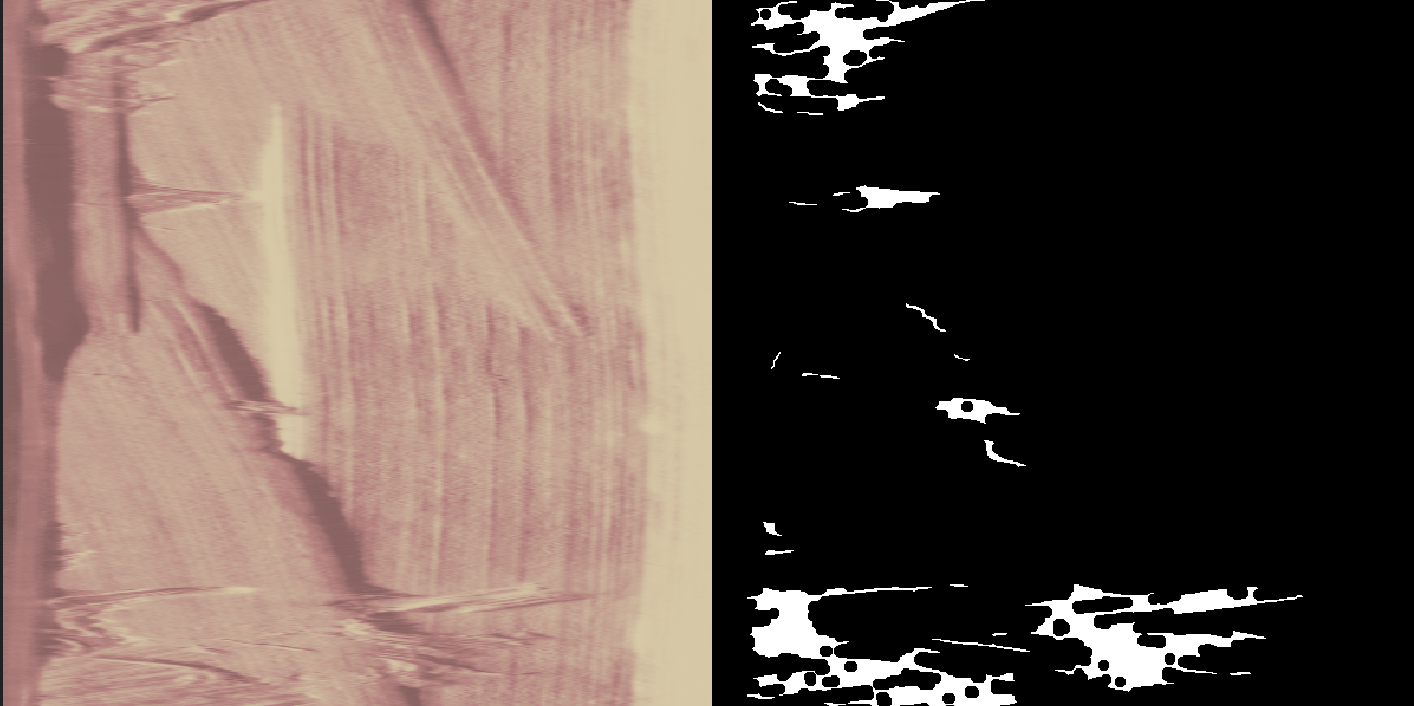

### 1.3 Hybrid Classification Architecture

Our hybrid architecture is present in the function `inspectPart.m`. It includes the classical evidence extraction (scratch/brush detectors) + transfer-learned ResNet-18 classifier + rule-based baseline, combined in `inspectPart.m`. AI gives the primary PASS/FAIL decision with confidence; classical evidence gives traceability, interpretability, and a sanity-check baseline, with the ability to override the AI in chosen situations. This is a required function for this project and the function that was put through the final batch test. 

### 1.4 Batch Testing Methodology

The BTAD datasets come pre-sorted as `"test/" `and` "train/"`. Our batch testing was run locally, using the full `"test/"` dataset. This was done to establish efficiency, while reducing runtime on this current live script, and preventing excess consumption of user's storage space. The batch testing further runs on a two-tier results system. The baseline results cover the whole defect batch (test/). However, since our classical detection doesn't track super-fine scratches and the limitations of resnet18 cause the AI to completely miss them too, a second batch test, "`--- Fine Scratches Excluded -- PRIMARY RESULT ---" `is the set that our detection system was designed for. Super-fine scratches being incorrectly passed by our AI classifier with high confidence can be shown in the live demonstration's image 19, which is why the second dataset excluding them is necessary.

## 2. Results & Analysis (Deliverables)

In-depth analysis of the results of our main project appear in this section. The full dataset batch testing produced two results: metrics for the datasets with all defects and metrics for the dataset excluding super-fine scratches. There is also a live, per-image demo of the hybrid inspection function (inspectPart.m) in action.

### 2.1 Baseline: Batch Testing with All Defects Included

For the sake of transparency, this first, failure batch result displays how the detection pipelines works on the whole testing dataset. The testing dataset includes 200 defective images and 30 clean images. Of all 230 images,** the system's final decision matched the true label 53.48% of the time**. Only being correct half the time is terrible for an inspection system. An actual yield of 13.04% means that only a few of the images (30/230) were actually clean images, yet our system's predicted yield was passing nearly 60% of the images as clean. However, there was a silver lining.

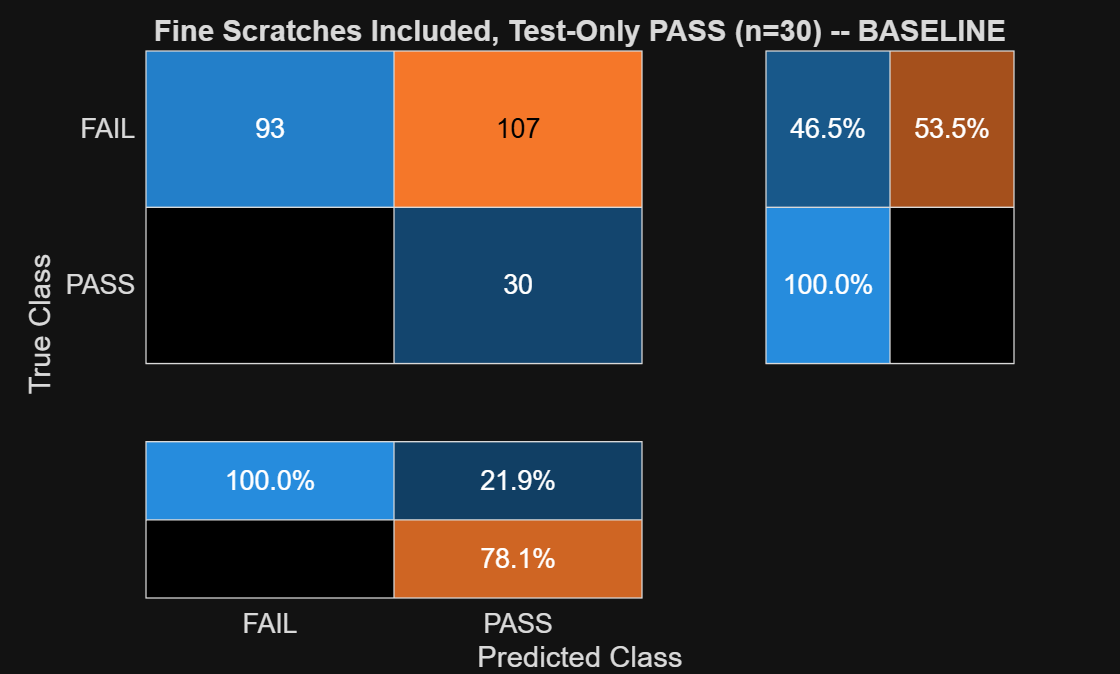

=== Fine Scratches Included, Test-Only PASS (n=30) -- BASELINE ===


Generated:          29-Jul-2026 22:14:27


PASS source:        test/ok only (n=30, no leakage)


Test set size:       230


Accuracy:            53.48%


Actual yield:        13.04%


Predicted yield:     59.57%


Defect rate:         40.43%


False reject rate:   0.00%


False accept rate:   53.50%


AI/rule disagreement rate: 6.96%


%% BASELINE RESULT (All defects)
% This is one of two precomputed full-dataset result files committed to
baselineLabel = "Fine Scratches Included, Test-Only PASS (n=30) -- BASELINE";
baselineFile  = fullfile(imageSampleSetsDir, "fullDatasetResults_test30.mat");

if ~isfile(baselineFile)
    warning("batchTestRunner:missingResultFile", ...
        "%s not found.\n", baselineFile);
else
    B = load(baselineFile, "fullResults");
    frBaseline = B.fullResults;

    figure("Name", baselineLabel);
    cmBaseline = confusionchart(frBaseline.confMat, frBaseline.classNames);
    cmBaseline.Title = baselineLabel;
    cmBaseline.RowSummary = "row-normalized";
    cmBaseline.ColumnSummary = "column-normalized";

    fprintf("=== %s ===\n", baselineLabel);
    fprintf("Generated:          %s\n", string(frBaseline.dateGenerated));
    if isfield(frBaseline, "passSource")
        fprintf("PASS source:        %s\n", frBaseline.passSource);
    end
    fprintf("Test set size:       %d\n", frBaseline.numTest);
    fprintf("Accuracy:            %.2f%%\n", frBaseline.accuracy * 100);
    fprintf("Actual yield:        %.2f%%\n", frBaseline.yieldActual * 100);
    fprintf("Predicted yield:     %.2f%%\n", frBaseline.yieldPredicted * 100);
    fprintf("Defect rate:         %.2f%%\n", frBaseline.defectRate * 100);
    fprintf("False reject rate:   %.2f%%\n", frBaseline.falseRejectRate * 100);
    fprintf("False accept rate:   %.2f%%\n", frBaseline.falseAcceptRate * 100);
    fprintf("AI/rule disagreement rate: %.2f%%\n", frBaseline.disagreementRate * 100);
end

While it would have been easy to mark this run as an absolute failure, there were a few key distinctions that made our team rethink the results. A false reject rate of 0% means that **all clean images were being passed correctly**, making the clean images a non-issue. This naturally means that the defects are the issue. This is supported by the fact that the false accept rate is 53.50%, meaning just over **half of defects are being counted as passing**. Furthermore, the AI disagreement rate was a low 7%, indicating that both the classical and AI had the same tendency to overlook a large span of defects. Taken all together, a hypothesis was born. This systemic issue is a consequence of the super-fine scratch defect. This is where the second batch test was created.

### 2.2 Refined: Batch Testing Excluding Super-fine Scratch Defect

This second batch excludes the last 120 defects, which completely eliminates super-fine scratches (along with 12 other normal defects). This change causes the **accuracy jumps from 53.48% to 100%**, nearly doubling. This accuracy is evident in the **false acceptance rate going from 53.5% all the way down to 0%**, indicating that **defects are no longer passing through the system undetected.** Since super-fine scratches account for 54% (108/200) of all defects and all 107 defects that falsely passed the baseline no longer pass, this implies that all the 107 false acceptances were part of the 108 super-fine scratch defects, with only 1 super-fine defect actually being detected in both batches (image 107, shown in Live Demo Image 20). 

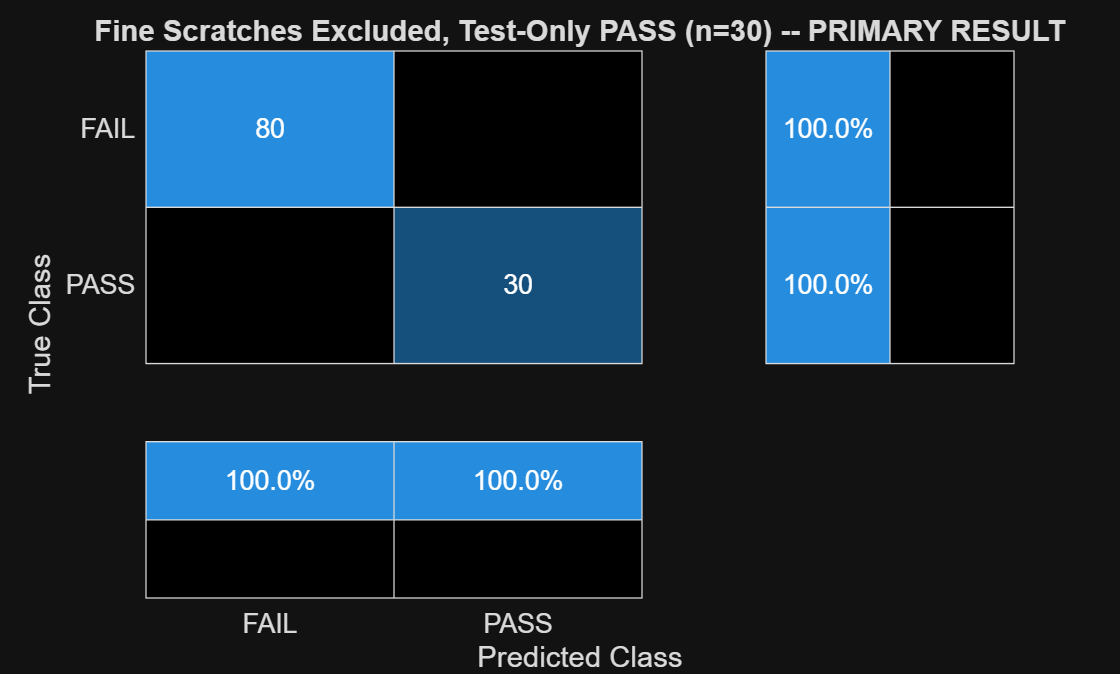


=== Fine Scratches Excluded, Test-Only PASS (n=30) -- PRIMARY RESULT ===


Generated:          29-Jul-2026 22:08:34


PASS source:        test/ok only (n=30, no leakage)


Test set size:       110


Accuracy:            100.00%


Actual yield:        27.27%


Predicted yield:     27.27%


Defect rate:         72.73%


False reject rate:   0.00%


False accept rate:   0.00%


AI/rule disagreement rate: 4.55%


%% Final Results
% Same PASS set (test/ok, n=30), same defect source (test/ko), with the ONLY
% difference being fine-scratch defects (idx >= 80) are excluded. This
% isolates fine scratches' effect on accuracy/FAR since every other
% variable is held constant. 
primaryLabel = "Fine Scratches Excluded, Test-Only PASS (n=30) -- PRIMARY RESULT";
primaryFile  = fullfile(imageSampleSetsDir, "fullDatasetResults_noFineScratch_test30.mat");

if ~isfile(primaryFile)
    warning("batchTestRunner:missingResultFile", ...
        "%s not found.\n", primaryFile);
else
    P = load(primaryFile, "fullResults");
    frPrimary = P.fullResults;

    figure("Name", primaryLabel);
    cmPrimary = confusionchart(frPrimary.confMat, frPrimary.classNames);
    cmPrimary.Title = primaryLabel;
    cmPrimary.RowSummary = "row-normalized";
    cmPrimary.ColumnSummary = "column-normalized";

    fprintf("\n=== %s ===\n", primaryLabel);
    fprintf("Generated:          %s\n", string(frPrimary.dateGenerated));
    if isfield(frPrimary, "passSource")
        fprintf("PASS source:        %s\n", frPrimary.passSource);
    end
    fprintf("Test set size:       %d\n", frPrimary.numTest);
    fprintf("Accuracy:            %.2f%%\n", frPrimary.accuracy * 100);
    fprintf("Actual yield:        %.2f%%\n", frPrimary.yieldActual * 100);
    fprintf("Predicted yield:     %.2f%%\n", frPrimary.yieldPredicted * 100);
    fprintf("Defect rate:         %.2f%%\n", frPrimary.defectRate * 100);
    fprintf("False reject rate:   %.2f%%\n", frPrimary.falseRejectRate * 100);
    fprintf("False accept rate:   %.2f%%\n", frPrimary.falseAcceptRate * 100);
    fprintf("AI/rule disagreement rate: %.2f%%\n", frPrimary.disagreementRate * 100);
end

This result signifies that both the AI and the classical detection are both missing these super-fine, tiny defects.

### 2.3 Live Demonstration

This live demo is a small display of `inspectPart.m `in action. **A small batch of images can be selected with the slider** and this script will report detailed per-image stats. The first 10 images are clean images from the training set, while images 11-20 are defect images. 

%% The Live Demo

if ~isfolder(sampleDataFolder)
    warning("batchTestRunner:noSampleImages", ...
        "%s not found. Skipping Part B (live demo).", sampleDataFolder);
    return;
end

% Download the trained net from GitHub Releases if it isn't already here
if ~isfile(netMatFile)
    fprintf("Trained network not found locally. Downloading from GitHub Releases...\n");
    fprintf("  %s\n", netReleaseURL);
    try
        websave(netMatFile, netReleaseURL);
        fprintf("Download complete: %s\n", netMatFile);
    catch ME
        if isfile(netMatFile)
            delete(netMatFile);
        end
        error("batchTestRunner:downloadFailed", ...
            "Could not download the trained network from:\n  %s\nError: %s\n" + ...
            "Check that netReleaseURL above is correct, or manually download " + ...
            "%s from the repo's Releases page and place it in %s.", ...
            netReleaseURL, ME.message, netFileName, repoDir);
    end
end

S = load(netMatFile);
net           = S.netTransfer;
netClassNames = S.classNames;

imdsSample = imageDatastore(sampleDataFolder);   % flat images/ folder, no subfolders
numSample = numel(imdsSample.Files);

% True labels come from filename PREFIX ("clean_" / "defect_"), not
% folder names -- sample_test_02/images/ has no subfolder structure.
trueLabelsAll = strings(numSample, 1);
for i = 1:numSample
    [~, name, ~] = fileparts(imdsSample.Files{i});
    if startsWith(name, "clean_", "IgnoreCase", true)
        trueLabelsAll(i) = "PASS";
    elseif startsWith(name, "defect_", "IgnoreCase", true)
        trueLabelsAll(i) = "FAIL";
    else
        warning("batchTestRunner:unrecognizedFilePrefix", ...
            "File '%s' doesn't start with 'clean_' or 'defect_' -- true label unknown, marking as FAIL by default. Check this filename.", name);
        trueLabelsAll(i) = "FAIL";
    end
end

%% ===================== INTERACTIVE IMAGE SELECTOR =========================
% Pick which sample image to inspect.
imageIndex = 19;

%% ===================== INSPECTION RESULT FOR SELECTED IMAGE ================
imageIndex = max(1, min(numSample, round(imageIndex)));   % clamp to valid range

I = readimage(imdsSample, imageIndex);
[~, thisName, thisExt] = fileparts(imdsSample.Files{imageIndex});
trueLabel = trueLabelsAll(imageIndex);

fprintf("\n=== Image %d of %d: %s%s (true label: %s) ===\n", ...
    imageIndex, numSample, thisName, thisExt, trueLabel);


=== Image 19 of 20: defect_0100.png (true label: FAIL) ===


Final Decision:    PASS
=== Hybrid Inspection Result ===
AI Raw Decision:   PASS (confidence 0.94)
Rule-Based Backup: PASS (scratchFail=0, brushFail=0)


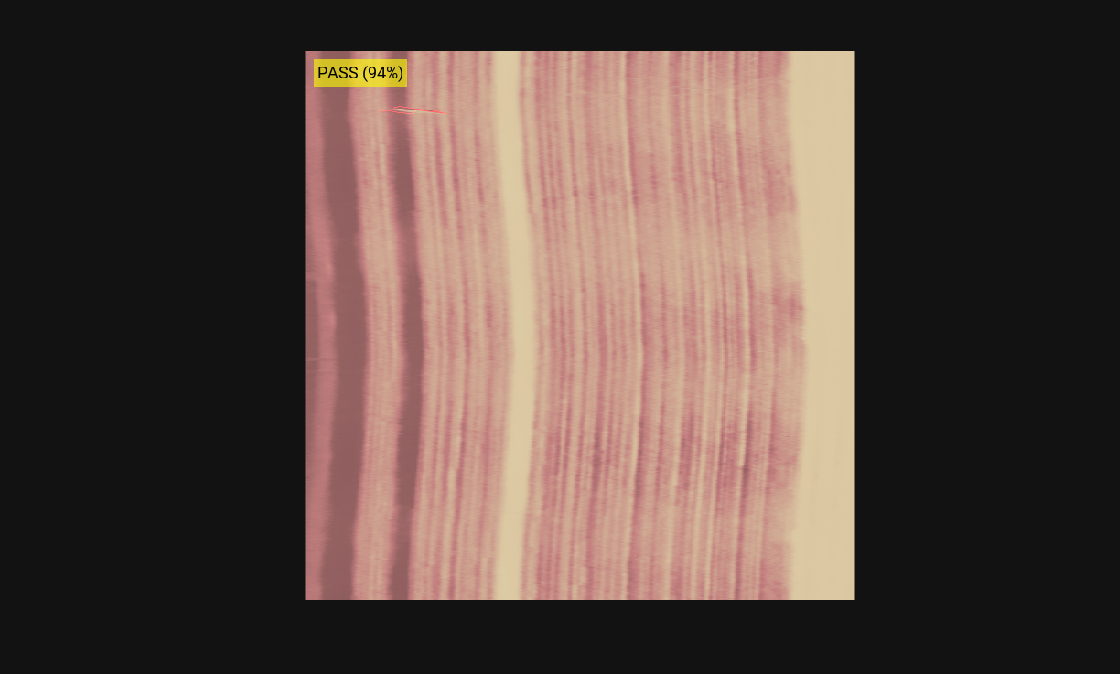


result = inspectPart(I, net, netClassNames, true);   % showDebug=true -> shows evidence overlay


isCorrect = strcmp(string(result.finalLabel), trueLabel);

fprintf("\n--- Full Stats for This Image ---\n");


--- Full Stats for This Image ---


fprintf("True label:              %s\n", trueLabel);

True label:              FAIL


fprintf("Final decision:          %s   %s\n", result.finalLabel, ternary(isCorrect, "(CORRECT)", "(WRONG)"));

Final decision:          PASS   (WRONG)


fprintf("AI raw decision:         %s (confidence %.2f)\n", result.aiRawLabel, result.confidenceScore);

AI raw decision:         PASS (confidence 0.94)


fprintf("Confidence override:     %s\n", ternary(result.overrideApplied, "YES -- baseline used instead of AI", "no"));

Confidence override:     no


fprintf("Rule-based baseline:     %s\n", result.baselineDecision);

Rule-based baseline:     PASS


fprintf("AI/baseline disagreement:%s\n", ternary(result.disagreementFlag, "YES", "no"));

AI/baseline disagreement:no


fprintf("Cross-detector agreement:%s\n", ternary(result.crossDetectorAgreement, "YES (scratch AND brush both flagged)", "no"));

Cross-detector agreement:no


fprintf("\nEvidence metrics:\n");


Evidence metrics:


evidenceFields = fieldnames(result.evidenceMetrics);
for f = 1:numel(evidenceFields)
    fprintf("  %-30s %.4f\n", evidenceFields{f}, result.evidenceMetrics.(evidenceFields{f}));
end

  scratch_NumRegions             1.0000
  scratch_TotalDefectPixels      263.0000
  scratch_LargestRegionArea      263.0000
  scratch_PercentageFlagged      0.0731
  scratch_MaxAspectRatio         21.4638
  scratch_MaxAngleDeviation      84.9452
  scratch_MeanAngleDeviation     83.9351
  scratch_IntensityContrast      18.4047
  brush_NumRegions               0.0000
  brush_TotalDefectPixels        0.0000
  brush_LargestRegionArea        0.0000
  brush_PercentageFlagged        0.0000
  brush_AvgSolidity              NaN
  brush_TextureDeficit           NaN
  brush_IntensityContrast        NaN
  combined_PercentageFlagged     0.0731



function out = ternary(cond, a, b)
if cond, out = a; else, out = b; end
end

### 2.4 Segment Defect Vs. Classical Detection

There is a separate live script for this titled `segmentDefectDemo.mlx`. Segment defect live script is independent from the detection pipelines and showcases s`egmentDefect.m`. This function uses a trained AI to produce a mask. A classical detection function was prepared for every dataset to allow you to compare segmentDefect's AI mask accuracy across all three datasets!

## 3. Design Decisions & Tradeoffs

This section covers important design decision and the consequences brought about by them. 

### 3.1 Confidence-Gated Override 

In the inspection system (`inspectPart.m`), a confidence-gated override (0.75 threshold) defers to the classical baseline when AI confidence is low. Prior to this addition, the AI gave the final answer with the classical acting as evidence. However, before our final batch tests, the addition of confidence thresholding was decided on from batch data on 510 images (all testing and training images excluding super-fine scratches). The results below are from the actual file .mat file created from testing: 

%% This code is actually unreproducable, since this used the
% pre-override version of inspectPart.m. Running it with current
% inspectPart will actually yield better results!

fprintf("Loaded results generated: %s\n", string(fr.dateGenerated));

Loaded results generated: 29-Jul-2026 17:35:18


if isfield(fr, "fineScratchCutoff") && isfield(fr, "numExcluded")
    fprintf("Fine-scratch cutoff used: idx >= %d (%d defect images excluded)\n", ...
        fr.fineScratchCutoff, fr.numExcluded);
    fprintf("Note: 120-119 = 1 less image excluded, which is a super-fine scratch defect");
    fprintf("left in due to idx cutting off at 81 and not 80. This fact is not ignored.\n");
end

Fine-scratch cutoff used: idx >= 81 (119 defect images excluded)


Note: 120-119 = 1, which is a super-fine scratch defect left in


Due to idx cutting off at 81 and not 80.



%  PERFORMANCE METRICS TABLE
Metric = [
    "Test Set Size";
    "Accuracy (%)";
    "Actual Yield (%)";
    "Predicted Yield (%)";
    "Defect Rate (%)";
    "False Reject Rate (%)";
    "False Accept Rate (%)";
    "AI/Rule Disagreement Rate (%)"
    ];

Value = [
    fr.numTest;
    fr.accuracy * 100;
    fr.yieldActual * 100;
    fr.yieldPredicted * 100;
    fr.defectRate * 100;
    fr.falseRejectRate * 100;
    fr.falseAcceptRate * 100;
    fr.disagreementRate * 100
    ];

classNames = string(fr.classNames);
passIdx = find(classNames == "PASS", 1);
failIdx = find(classNames == "FAIL", 1);

numPassTrue = sum(fr.confMat(passIdx, :));
numFailTrue = sum(fr.confMat(failIdx, :));

Notes = [
    "";
    "";
    sprintf("%d/%d", numPassTrue, fr.numTest);
    "";
    "";
    "";
    "";
    ""
    ];

MetricsTable = table(Metric, Value, Notes);

disp('--- Performance Metrics ---');

--- Performance Metrics ---


disp(MetricsTable);

                Metric                 Value       Notes  
    _______________________________    ______    _________

    "Test Set Size"                       510    ""       
    "Accuracy (%)"                     97.843    ""       
    "Actual Yield (%)"                 84.118    "429/510"
    "Predicted Yield (%)"              83.922    ""       
    "Defect Rate (%)"                  16.078    ""       
    "False Reject Rate (%)"            1.3986    ""       
    "False Accept Rate (%)"            6.1728    ""       
    "AI/Rule Disagreement Rate (%)"    2.1569    ""       




%  2. CONFUSION MATRIX TABLE
% Rows represent the ACTUAL state (FAIL or PASS)
Actual_Class = ["Actual FAIL"; "Actual PASS"];

predFAIL_actualFAIL = fr.confMat(failIdx, failIdx);
predPASS_actualFAIL = fr.confMat(failIdx, passIdx);
predFAIL_actualPASS = fr.confMat(passIdx, failIdx);
predPASS_actualPASS = fr.confMat(passIdx, passIdx);

Predicted_FAIL = [predFAIL_actualFAIL; predFAIL_actualPASS];
Predicted_PASS = [predPASS_actualFAIL; predPASS_actualPASS];

correctPctFAIL = 100 * predFAIL_actualFAIL / numFailTrue;
correctPctPASS = 100 * predPASS_actualPASS / numPassTrue;
errorPctFAIL   = 100 * predPASS_actualFAIL / numFailTrue;
errorPctPASS   = 100 * predFAIL_actualPASS / numPassTrue;

Correct_Percentage = [
    sprintf("%.1f%%", correctPctFAIL);
    sprintf("%.1f%%", correctPctPASS)
    ];

Error_Percentage = [
    sprintf("%.1f%% (Missed)", errorPctFAIL);
    sprintf("%.1f%% (Wrongly Rejected)", errorPctPASS)
    ];

ConfusionTable = table(Actual_Class, Predicted_FAIL, Predicted_PASS, Correct_Percentage, Error_Percentage);

disp('--- Confusion Matrix ---');

--- Confusion Matrix ---


disp(ConfusionTable);

    Actual_Class     Predicted_FAIL    Predicted_PASS    Correct_Percentage        Error_Percentage     
    _____________    ______________    ______________    __________________    _________________________

    "Actual FAIL"          76                 5               "93.8%"          "6.2% (Missed)"          
    "Actual PASS"           6               423               "98.6%"          "1.4% (Wrongly Rejected)"





%%

For discussion on the override design, the AI/Rule disagreement rate is the most important factor. Using the debug tools and finding the confidence of all scores, the 11 disagreement cases (11/510 = 2.1569%) were split into three distinct categories:

- ** 8 disagreement cases, all below 75% confidence, all fixed by the override.** Every one of these has the classical baseline correct and the AI wrong:

- 4 true-PASS images where AI said FAIL (confidence 0.74, 0.52, 0.56, 0.66) — baseline correctly said PASS

- 4 true-FAIL images where AI said PASS (confidence 0.72, 0.63, 0.52, 0.53) — baseline correctly said FAIL

- **3 disagreement cases at high confidence** (0.97, 0.82, 0.96), all correct on the AI's part. This includes 

- In all 3, the AI was right and the classical baseline was wrong (specifically brush detection)

- The false rejections and false acceptances that BOTH AI and Classical got wrong were:

-  2 true-PASS images labeled as defective (by AI and brushDetection specifically)

- 1 defect image labeled as PASS (The 1 super-fine defect included in this batch test)

This design decision was actually **corrects every sub-threshold disagreement error** with zero downside in this dataset*. *Applying the confidence-gated override corrects 8 low-confidence AI errors, while not touching the AI's answer when it is confidently correct. However, this same batch test also revealed brush detection's tendancy to produce false postiives (Explored in Remaining Challenges).

### 3.2 Scratch Detection Threshold

Another design change made to the hybrid function was changing the decision rule for `scratchDetection.m`. Inital testing used MeanAngleDeviation < 10 to determine if a mask was passable. However, after introducing a grain filtering threshold, the scratch defect mask's vertical false positives were removed causing angle deviation to reflect the angle of noise. As such, the mean angle deviation threshold was no longer meaningful (notice how mean angle deviation goes from <10 to 56.73)`: `

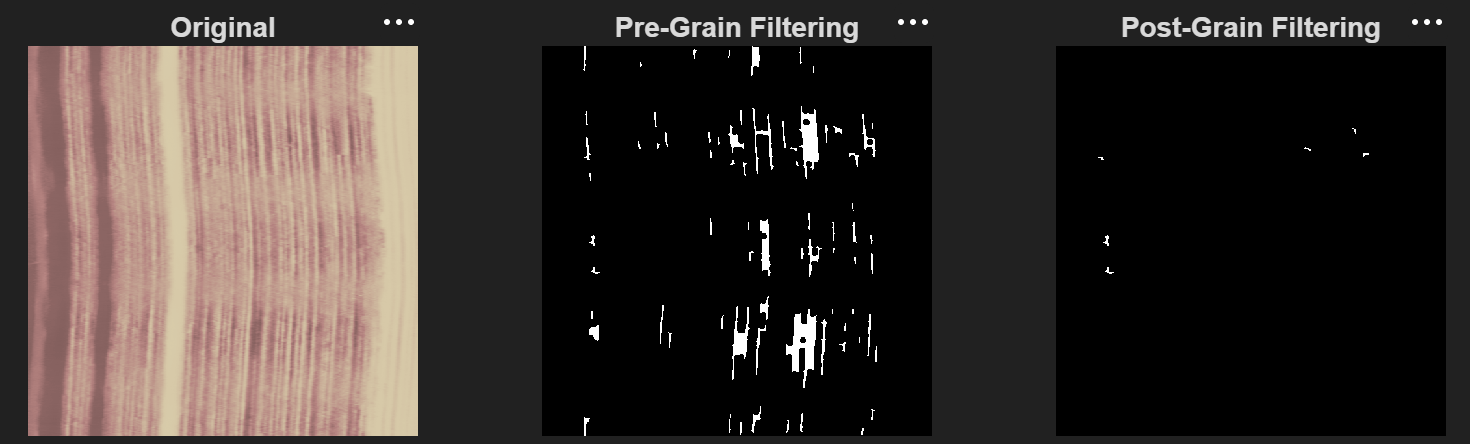

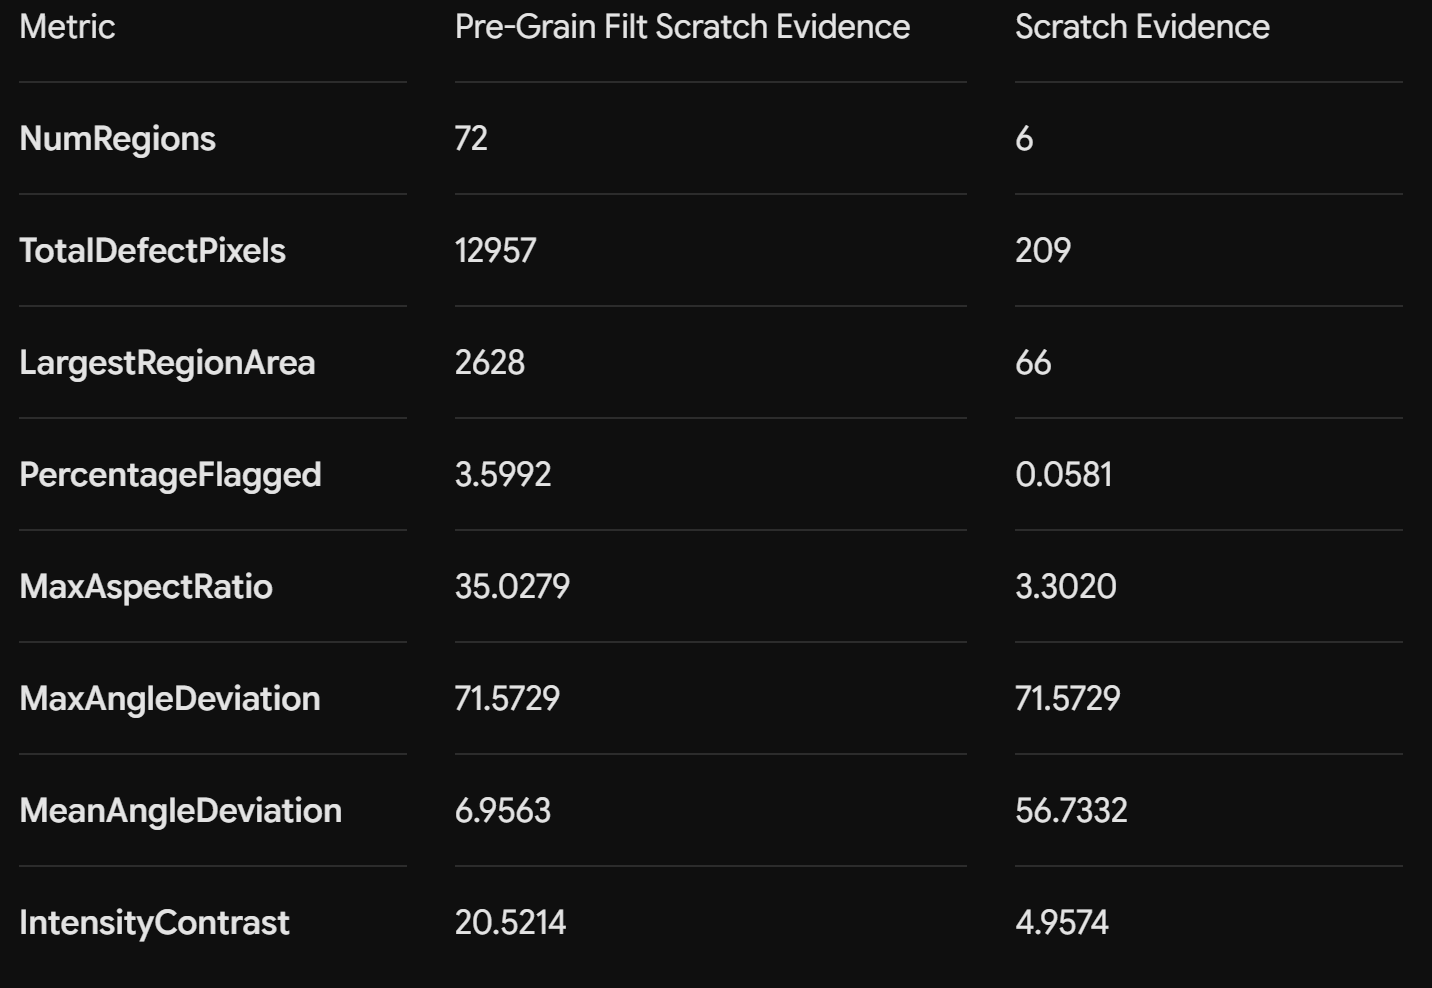

While that metric became unusable, largest region area became promising. Testing the metrics on 100 images showed that the **minimum defect area was 871px**, while the **max clean area was 123px. **This makes the 300 px LargestRegionArea a perfect threshold for determining if an image has a scratch defect or not (as stated in `inspectPart.m`). 

**Validation result on that same 50/50 batch:**

- **Recall: 100%** (50/50 scratch defects correctly caught)

- **False positives: 0** (0/50 clean images wrongly flagged)

This result can be replicated by running `scratchDetection.m` on clean and defect images that include scratches.

### 3.3 Unused finescratchDetection.m

By far the biggest tradeoff was the removal of `finescratchDetection.m `(`hairlineScratchDetection.m `in the repository). Cutting off the ability to detect more than half of the defects in the dataset is steep, but it highlights a notable limitation in classical defect detection. There is no way to differentiate noise from a scratch that is a few pixels tall. This is best shown through the 30 defect vs 30 clean image comparison done on the fine-scratch detector:

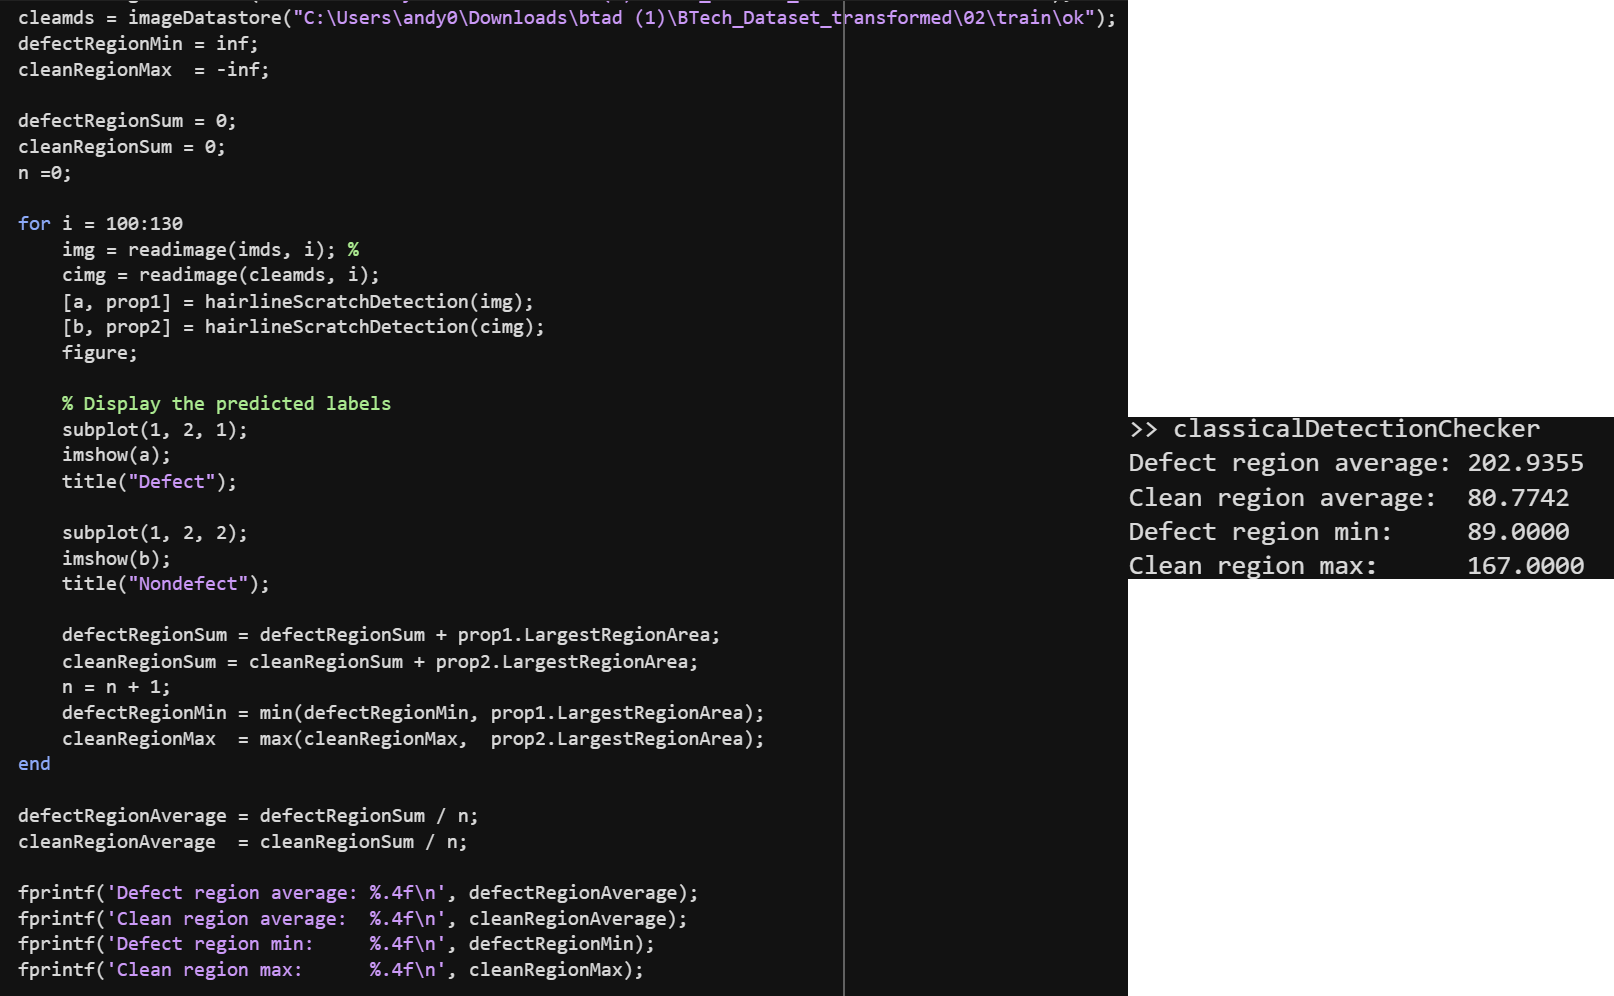

On the left is the code, and on the right is the output. The positive is that there is a positive correlation between bigger region area and a defect being there. In defect images, the largest region average (202.93 px) is more than double the average largest region area in a clean image (80.77 px). However, the minimum defect region and maximum clean region have significant overlap. This overlap means that some super-fine defect would still pass inspection, while more clean images would be thrown out. In image processing terms, if kept in the final detection pipeline, `finescratchDetection.m` would add recall but at the cost of an already-working system's precision. In its current state, it is a net negative for a hybrid inspection pipeline, especially one where false positives (rejecting good parts) have real cost. For those reasons, this function remains unused in the final product.

### 3.4 brushDetection.m's Cross-Grain Sensitivity

Cross-grain is defined as any non-vertical grain that appears in this dataset.

## 4. Remaining Challenges

This section will cover issues unaddressed due to time constrains that reduce the effectiveness of this detection pipeline. If this were a larger scale project, these would be key areas to look to refine. I have left these issues, along with potential cause and fixes listed.

### Why did ResNet-18's fail to capture smaller defects?

In the final testing, the AI trained on** ResNet-18 neural network completely failed to detect the super-fine scratch defect**s, despite doing good on the other two defects. This issue leads to the lower accuracy when the detection system analyses the whole batch of defects. A reasonable, and highly-**probable cause of this is ResNet18's 224x224 pixel input size**.  Resizing images to a 224x224 input size usually causes a permanent loss of image information. With super-fine scratch defects being mere pixels in height, it is a reasonable that the **compression from 600x600 to 224x224 would make them compress them into non-existence**. 

A fix worth looking into is patches. The patch method cuts a large, high-resolution image into a grid of smaller, manageable pieces called **patches**. Each piece is processed individually to keep fine details intact without overloading the computer's memory. Breaking an image into patches would preserve super-fine scratches more effectively. The reason this method was not implemented was due to the time constraint and logistics. Recall that all defects in this dataset are local, meaning they do not span the whole image. By breaking an image into patches, each patch would have to be relabeled as "clean" or "defective". Doing this for 200 images would not only be time consuming, but also a mess to reorganize.

### Why do some ground truths seem inaccurate?

During the initial stages of categorizing defects, some ground truths masks stood out. A ground truth is a human-verified reference image showing the exact pixel-level location of an object. This section calls in to question some seemingly inaccurate ground truths. 

#### Cross-grain Inconsistency

Defect labeled 0003 is shown below, alongside its ground truth:

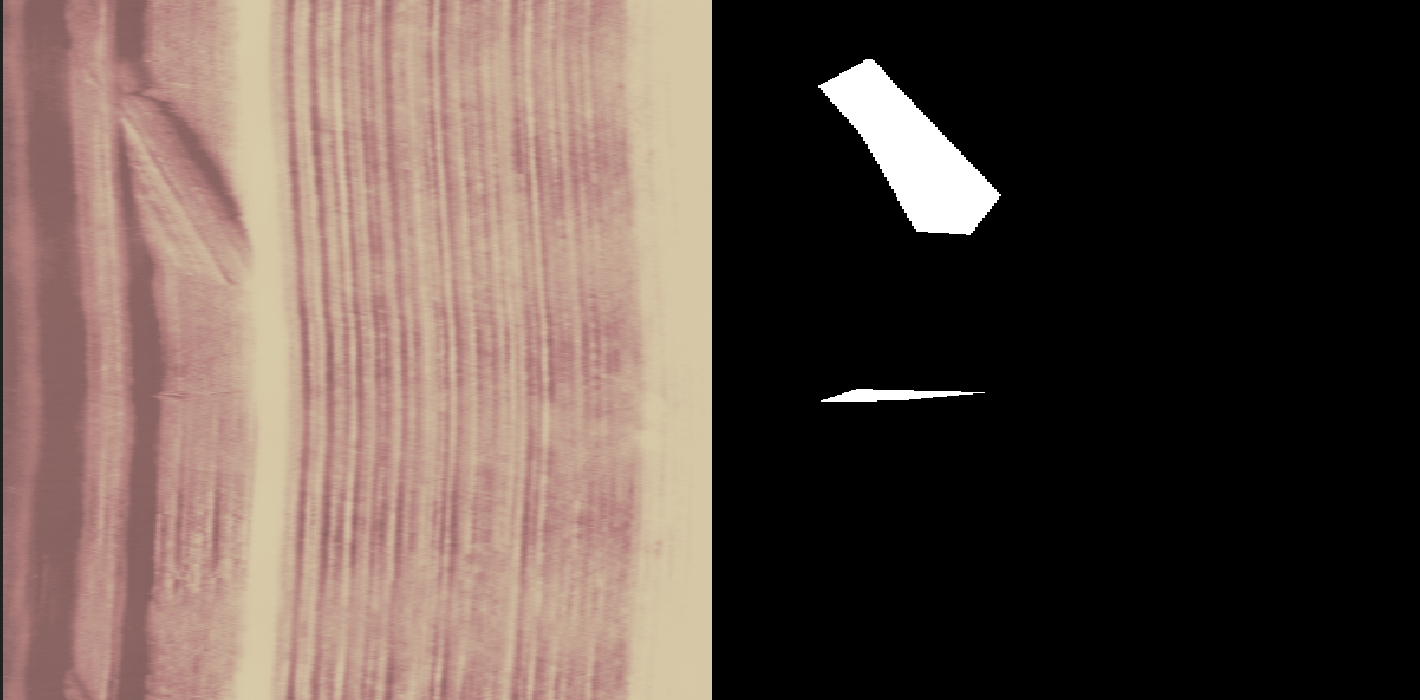

Test image 0000 is shown below, alongside its ground truth:

### Why does brush detection produce random false positives?

### What happened to the 12 unaccounted images in the Final Batch Test?

This open-ended question now has an answer! When I wrote the code for the final batch tests in Results & Analysis that excluded super-fine scratch defects, I set the cutoff to be anything greater than or equal to 80. This removed all 108 super-fine scratch defects, but also removed 12 genuine brush and scratch defects. These defects are numbered 0188-0199 in the defect dataset. This one fact calls into question the 100% accuracy achieved, as 12 more defects is a non-negligible amount to skip past. Thus, these two images prove that accuracy stays at 100% when these images are accounted for. Below is the code and the command window (for documentation & reproducibility):

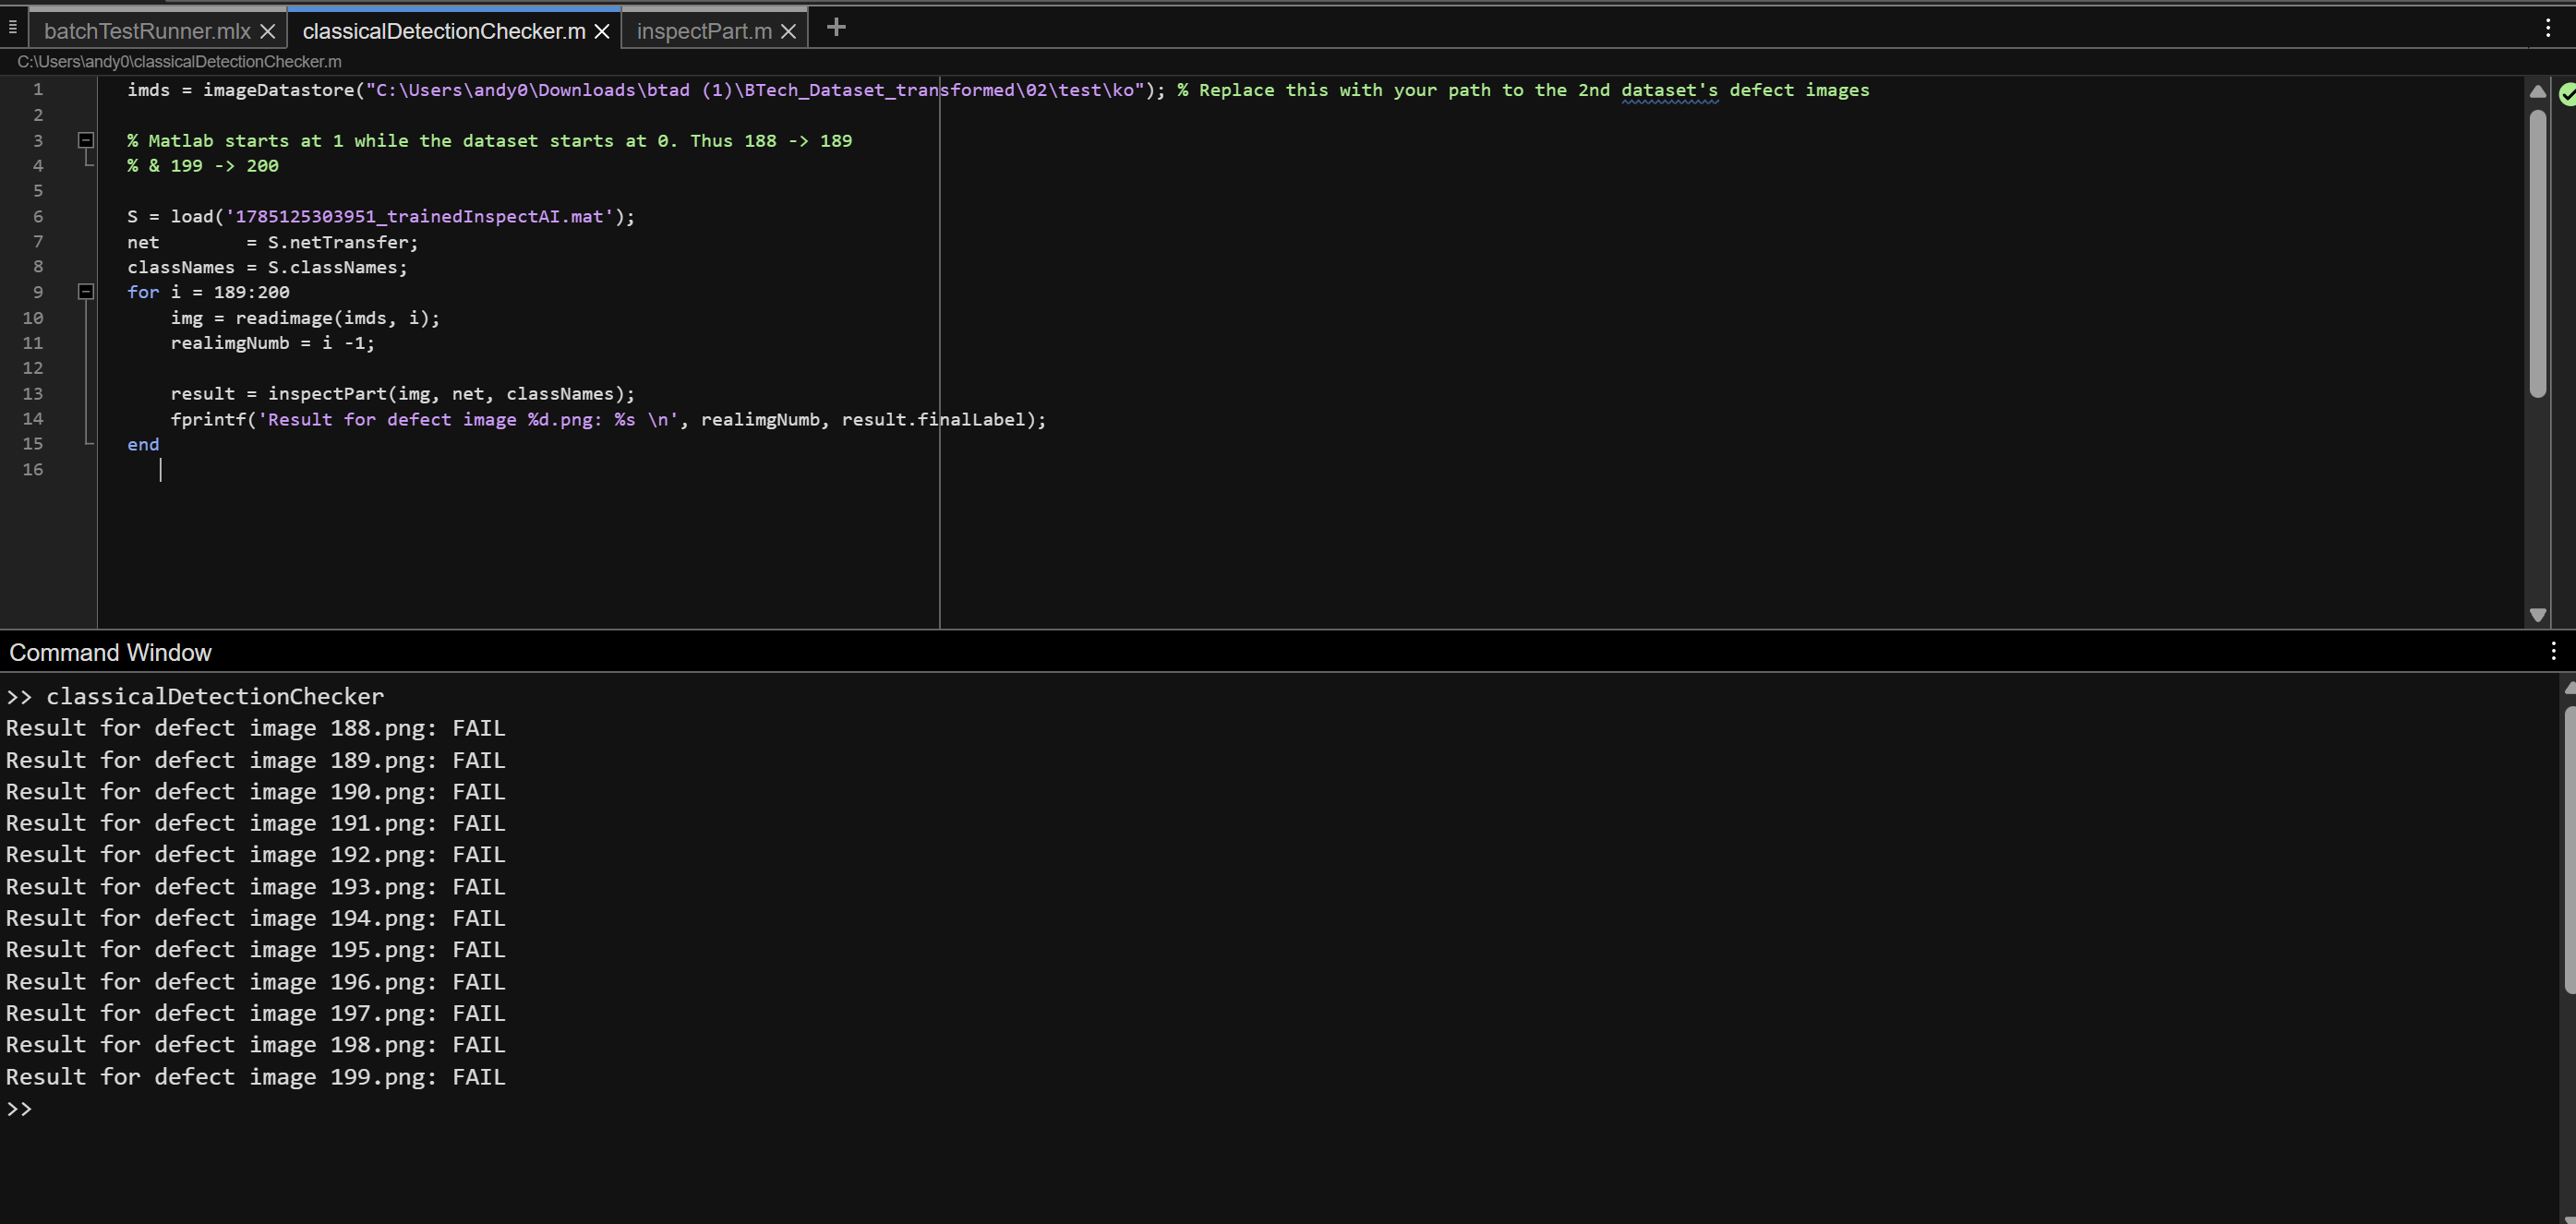

If you want to run this yourself, you would need to install BTAD's dataset, which is not native to this repository and replace the file path used with your own file path to the datasets '02/test/ko'. However, using `inspectPart.m `on the unaccounted defect images proves that the 100% accuracy of the final batch testing still holds up.

## Final Remarks 

Overall, there were many lessons learned from creating this project. Each piece of the final system passed through many iterations and there was always something to improve upon. The trade-offs that were made necessitated good documentation and hard evidence to back them up. This cold, indifferent evidence created the hardest decisions, where hours of time was spent only for the idea to not work in practice (something we have become very familiar with during the timeline of this project). However, despite all the struggle, there was so much fun in the process of creating and testing. In image processing, perfection may not be feasible, but that shouldn't stop us from trying